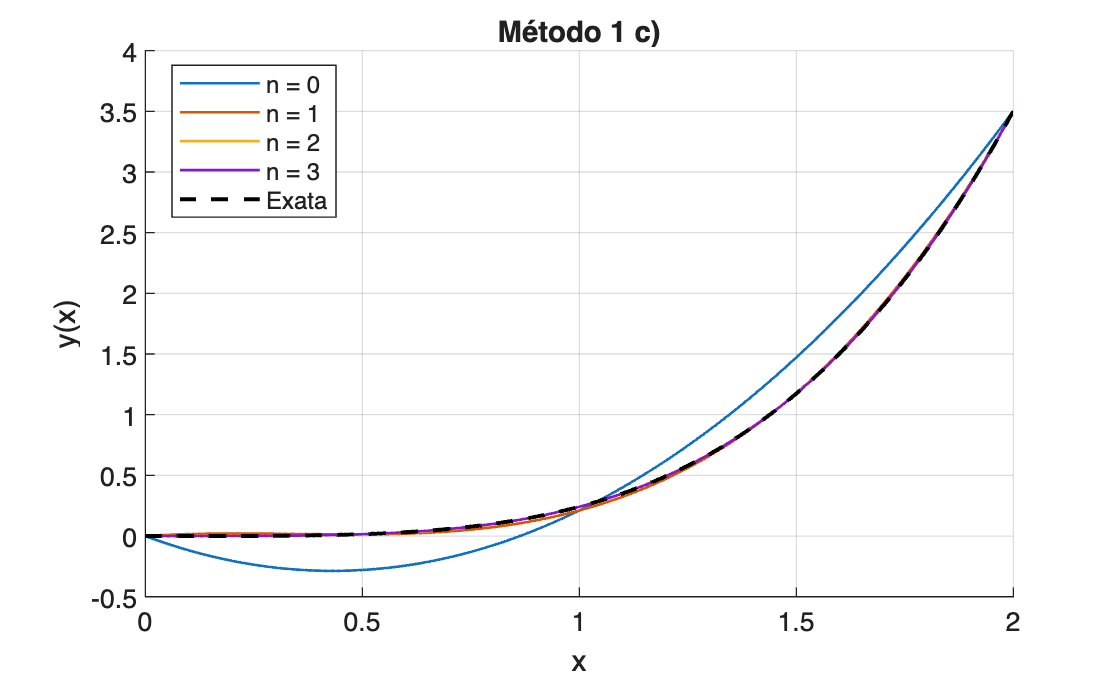

%%alínea c) - método1
format long

% Dados do problema
a = 0; 
b = 2;
y0 = 0; 
y1 = 6 + 6*cos(2);

% Funções q(x) e r(x)
q = @(x) 1 + 0*x;
r = @(x) 3 * x.^2;

% Solução exata fornecida
y_exata = @(x) 6*cos(x) + 3*(x.^2 - 2);

x_vals = linspace(a, b, 1000);

figure;
hold on;

% Testar para vários n
for n = 0:3
    u = metodo1c(n, q, r, a, b, y0, y1);
    ulista = arrayfun(u, x_vals);
    
    % plot das aproximações
    plot(x_vals, ulista, 'LineWidth', 1, 'DisplayName', ['n = ' num2str(n)]);
end

% plot da solução exata
plot(x_vals, y_exata(x_vals), 'k--', 'LineWidth', 1.5, 'DisplayName', 'Exata');

xlabel('x');
ylabel('y(x)');
title('Método 1 c)');
legend('Location', 'best');
grid on;
hold off;

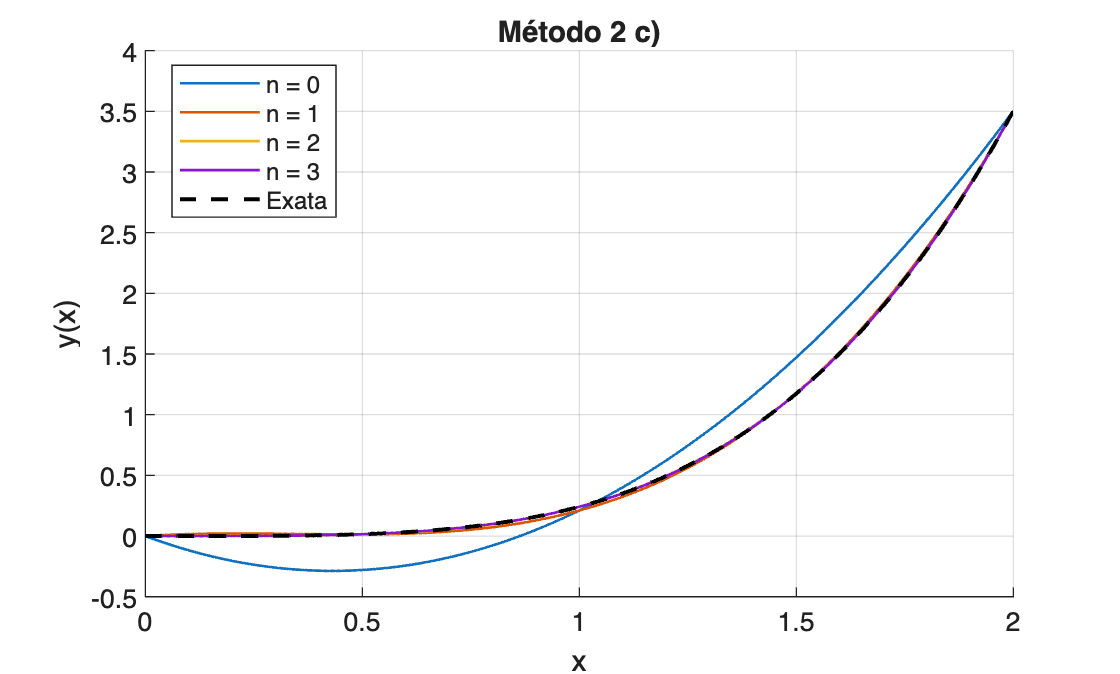


%% - metodo2

figure;
hold on;

for n = 0:3
    u = metodo2c(n, q, r, a, b, y0, y1);
    ulista = arrayfun(u, x_vals);
    
    % plot das aproximações
    plot(x_vals, ulista, 'LineWidth', 1, 'DisplayName', ['n = ' num2str(n)]);
end

% plot da solução exata
plot(x_vals, y_exata(x_vals), 'k--', 'LineWidth', 1.5, 'DisplayName', 'Exata');

xlabel('x');
ylabel('y(x)');
title('Método 2 c)');
legend('Location', 'best');
grid on;
hold off;